Aristotle University of Thessaloniki 

Department of Electrical and Computer Engineering 

Telecommunications Division

Georgios Tsantikis 10722

# **Communication Systems II **

## Literature Review

In this section, we present the state-of-the-art about Constellation Design for Simultaneous Wireless Information and Power  Transfer (SWIPT).

...

# TASK 1: 

In this task, we provide theoretical  analysis about **PAPR** (peak-to-average power ratio) versus 𝑑𝑚𝑖𝑛  for the constellations **16-PAM**, **16-PSK**, and** 16-QAM**, and verify the results in Fig. 2 of [R1] through simulation.  We consider Es to have a fixed value for all the contellations , which ensures consistency and comparability in system design and performance evaluation.

 (Eg : energy of the pulse, Es : average symbol energy)

## Theoretical  analysis

**16-PAM (Pulse Amplitude Modulation) : **

In PAM , the bits of the imformation are mapped to the amplitude of the pulses. In 16-PAM (M=16, grade of the modulation), we transfer with each symbol  $\log_2 \left(M\right)=4$bits. The minimum Euclidean distance between adjacent points of the constellation equals : $\textrm{dmin}=2\sqrt{\textrm{Eg}}$ , where $\textrm{Eg}=\frac{3\;\textrm{Es}}{M^2 -1}$ , which means that as M decreases, Eg increases , so $\textrm{dmin}$ increases too. Also, knowing that $\textrm{PAPR}=\frac{3\;{\left(\mathit{\mathbf{M}}-1\right)}^2 }{{\mathit{\mathbf{M}}}^2 -1}$** , ** we conclude that as **dmin **(corresponds to the amplitude separation between adjacent symbols) increases, **PAPR** decreases. In other words, this is because a larger amplitude separation between symbols decreases the probability of symbol combinations that result in constructive interference and high peak amplitudes.

Es = 1; %it has to be the same for all the constellations
M=16; % 16-PAM
phase_PAM=0; % Phase equals zero for M-PAM constellations
Eg = 3* Es / (M^2-1);
dmin_PAM = 2*sqrt(Eg);

s_PAM=-(M-1)*sqrt(Eg):dmin_PAM:(M-1)*sqrt(Eg); % sumbols of the constellation
PAPR_PAM= (3*(M-1)^2)/(M^2-1) % PAPR for M-PAM

PAPR_PAM = 2.6471

Plotting 16-PAM Constellation :

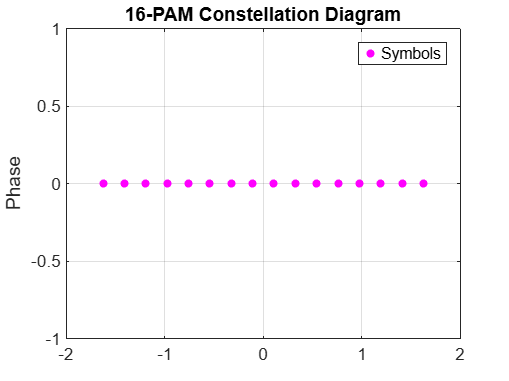

plot(s_PAM, phase_PAM, 'm.', MarkerSize=14)
title('16-PAM Constellation Diagram')
ylabel('Phase')
legend('Symbols')
grid on

**16-PSK (Phase Shift King):**

In PSK the information is conveyed in the phase of sinusoidal waveforms of the same frequency and amplitude. Since the amplitude of the transmitted signal remains constant, the energy of each symbol is the same. Consequently, the maximum energy (Emax) is equal to Es, so the maximum power is equal to the average power (P=E/T). Therefore **PAPR** typically equals one and it remains independent of the modulation order (**M**), as the energy distribution remains constant regardless of the number of symbols in the constellation. 

The minimum Euclidean distance between adjacent points of the constellation equals : $\textrm{dmin}=2\sqrt{\textrm{Es}}\;\sin \frac{\pi }{\mathit{\mathbf{M}}}$ , and deacreases as **M **increases.

In order to built PSK constellation we use** I/Q **Diagramms, in which τhe PSK signals consist of the sum of an Ιn-phase (**Ι**) component which is modulated in amplitude by the signal $\sqrt{\textrm{Es}}\;\cos \theta_{\mathit{\mathbf{i}}}$ and a Quadrature (**Q**) component which is modulated in amplitude by$\sqrt{\textrm{Es}}\;\sin \theta_{\mathit{\mathbf{i}}}$, where:  $\theta_{\mathit{\mathbf{i}}} =2\pi \;\frac{\mathit{\mathbf{i}}-1}{\mathit{\mathbf{M}}}$,*** i = 1, ... , M***. This diagram allows the representation of signals as complex numbers, where **Ι**  is considered the axis for real numbers and ***Q*** for imaginary numbers, respectively.

i=1:M;
theta = 2*pi*(i-1) / M;
dmin_PSK = 2*sqrt(Es)*sin(pi/M);

s_PSK = [sqrt(Es)*cos(theta); sqrt(Es)*sin(theta)]; %symbols of the constellation
PAPR_PSK = 1 % PAPR for M-PSK

PAPR_PSK = 1

Plotting 16-PSK Constellation: 

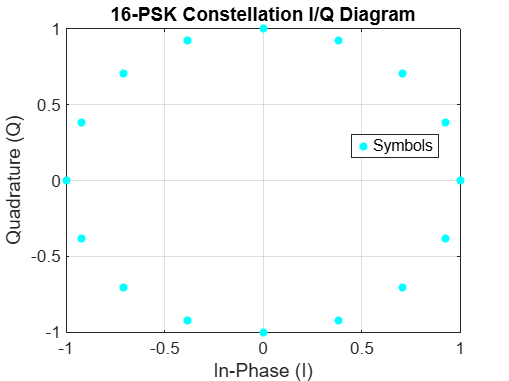

plot(sqrt(Es)*cos(theta), sqrt(Es)*sin(theta), 'c.', MarkerSize=14)
title('16-PSK Constellation I/Q Diagram')
xlabel('In-Phase (I)')
ylabel('Quadrature (Q)')
legend('Symbols', Location='best')
grid on

**16-QAM (Quadrature Amplitude Modulation):**

The M-QAM occurs from the M-PSK technique if the equal energy restriction of the sinusoidal waveforms is removed. Then, in addition to the phase, the amplitude (energy) will also change. ** I/Q **Diagramms can also be used for M-QAM . Now the symbols are ${\mathit{\mathbf{s}}}_{\mathit{\mathbf{i}}} =\left\lbrace \sqrt{{\mathit{\mathbf{E}}}_{\mathit{\mathbf{i}}} }\;\cos \theta_{\mathit{\mathbf{i}}} ,\sqrt{{\mathit{\mathbf{E}}}_{\mathit{\mathbf{i}}} }\;\sin \theta_{\mathit{\mathbf{i}}} \right\rbrace$where $E_i$ is the energy of the symbol with index i. In 16-QAM constellation, which is created from 2 x 4-PAM constellations, each symbol carries 4 bits of information, and the constellation consists of 16 points arranged in a 4x4 grid in the complex plane. The distance between adjacent points in the constellation corresponds to the minimum Euclidean distance (dmin). As **dmin** increases, the symbols in the constellation become more spaced out, leading to a reduction in the **PAPR**.

%calculating dmin for 2x4-PAM
N=4;
dmin_QAM = sqrt((6*Es)/(M-1));

amplitudes = (-N+1):sqrt(N):(N-1); % Normlised amplitude levels for both I and Q axes
[I, Q] = meshgrid(amplitudes); % Generate all possible combinations of amplitude levels for I and Q axes
s_QAM = I(:) + 1i * Q(:); % Combine the I and Q components to form complex symbols

%PAPR for M-QAM
P_peak = max(abs(s_QAM))^2;
P_average = mean(abs(s_QAM).^2);
PAPR_QAM = P_peak / P_average

PAPR_QAM = 1.8000

Plotting 16-QAM Constellation:

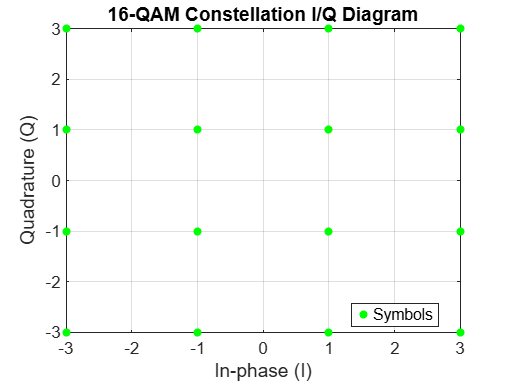

plot(s_QAM, 'g.', MarkerSize=14);
title('16-QAM Constellation I/Q Diagram');
xlabel('In-phase (I)');
ylabel('Quadrature (Q)');
legend('Symbols', Location='best')
grid on;

**CQAM (Circular Quadrature Amplitude Modulation)**

sebsgdbnsgnsrgfnsrgfn

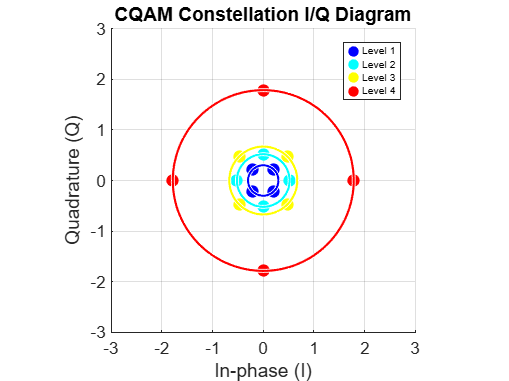

% Parameters
    Rcqam = 0.3;
    symbols_level = 4;
    num_levels_cqam = 4;

    % Calculate minimum distance and radii
    dmin_cqam = calculate_dmin_cqam(Rcqam, symbols_level);
    radii = calculate_radii_cqam(Rcqam, dmin_cqam, num_levels_cqam, symbols_level);
    positions = calculate_symbol_positions_cqam(num_levels_cqam, symbols_level, radii);

    % Plot the constellation with coordinates and circles
    figure;
    hold on;
    axis equal;
    colors = jet(num_levels_cqam);

    for level = 1:num_levels_cqam
        coords = positions{level};
        x_coords = real(coords);
        y_coords = imag(coords);
        scatter(x_coords, y_coords, 50, 'filled', 'MarkerFaceColor', colors(level, :));
        viscircles([0, 0], radii(level), 'Color', colors(level, :), 'LineWidth', 1.25);
    end
     legend(arrayfun(@(x) sprintf('Level %d', x), 1:num_levels_cqam, 'UniformOutput', false), 'FontSize', 6);

    grid on;
    title('CQAM Constellation I/Q Diagram');
    xlabel('In-phase (I)');
    ylabel('Quadrature (Q)');
    xlim([-3 3]);
    ylim([-3 3]);


    % Display calculated radii
    disp('Calculated Radii:');

Calculated Radii:


    disp(radii);

    0.3000    0.5196    0.6708    1.7861



Function definitions:

function dmin_cqam = calculate_dmin_cqam (Rcqam, symbols_level)
    angle_rad = 2 * pi / symbols_level;
    dmin_cqam = 2 * Rcqam * sin(angle_rad / 2);
end

function radii = calculate_radii_cqam(Rcqam, dmin_cqam, N, symbols_level)
    radii = zeros(1, N);
    radii(1) = Rcqam;
    if N > 1
        radii(2) = sqrt(dmin_cqam^2 + Rcqam^2 - 2 * Rcqam^2 * cos(2 * pi / symbols_level));
    end

    for i = 3:N
        R_prev = radii(i-1);
        R_prev_2 = radii(i-2);
        angle_diff = 2 * pi / symbols_level;

        % Calculate radius to maintain dmin with the previous level
        R_next_from_prev = sqrt(dmin_cqam^2 + R_prev^2 - 2 * R_prev^2 * cos(angle_diff));

        % Calculate radius to maintain dmin with level i-2
        angle_offset = (pi / symbols_level) * (mod(i,2) - mod(i-2, 2));
        R_next_from_prev_2 = sqrt(dmin_cqam^2 + R_prev_2^2 - 2 * R_prev_2^2 * cos(2 * angle_diff + angle_offset));

        % Choose the maximum radius to satisfy both conditions
        radii(i) = max(R_next_from_prev, R_next_from_prev_2);
    end

    % Adjust the last radius to fulfill the total energy constraint
    if N > 1
        radii(N) = sqrt(N - sum(radii(1:N-1).^2));
    end
end

function positions = calculate_symbol_positions_cqam(num_levels_cqam, symbols_level, radii)
    positions = cell(1, num_levels_cqam);
    angles = linspace(0, 2 * pi, symbols_level + 1); % Include endpoint

    for level = 1:num_levels_cqam
        level_positions = [];
        level_angle_offset = (pi / symbols_level) * mod(level, 2);
        level_angles = angles(1:end-1) + level_angle_offset; % Exclude endpoint

        for angle = level_angles
            x = radii(level) * cos(angle);
            y = radii(level) * sin(angle);
            level_positions = [level_positions, x + 1i * y];
        end

        positions{level} = level_positions;
    end
end

## Verification of the results in Fig. 2 of [R1]

Plotting PAPR versus dmin of CQAM (N=4 and N=8) and some well-known modulation schemes (16-QAM, 16-PAM AND 16-PSK):

% Parameters for N=4
num_levels = 4;
symbols_per_level = 4;
R1 = 0.424;
R1_values = linspace(0, R1, 5);  % R1 values for which we want to calculate dmin and PAPR
[dmins_CQAM4, paprs_CQAM4] = evaluate_radii_metrics(R1_values, symbols_per_level, num_levels);

% Parameters for N=8
num_levels = 8;
R1_values = linspace(0, 0.2, 50);  % R1 values from 0 to 0.2

% Arrays for storing d_min and PAPR values
dmins_CQAM8 = arrayfun(@(R1) calculate_d_min(R1), R1_values);
paprs_CQAM8 = arrayfun(@(R1) calculate_papr_modified(R1, num_levels), R1_values);

% Output results
disp('Dmin and PAPR for N=4:');

Dmin and PAPR for N=4:


disp([dmins_CQAM4; paprs_CQAM4]);

         0    0.1499    0.2998    0.4497    0.5996
    4.0000    3.8989    3.5955    3.0899    2.3820




disp('Dmin and PAPR for N=8:');

Dmin and PAPR for N=8:


disp([dmins_CQAM8; paprs_CQAM8]);

         0    0.0082    0.0163    0.0245    0.0327    0.0408    0.0490    0.0571    0.0653    0.0735    0.0816    0.0898    0.0980    0.1061    0.1143    0.1224    0.1306    0.1388    0.1469    0.1551    0.1633    0.1714    0.1796    0.1878    0.1959    0.2041    0.2122    0.2204    0.2286    0.2367    0.2449    0.2531    0.2612    0.2694    0.2776    0.2857    0.2939    0.3020    0.3102    0.3184    0.3265    0.3347    0.3429    0.3510    0.3592    0.3673    0.3755    0.3837    0.3918    0.4000
    8.0000    7.9978    7.9911    7.9799    7.9643    7.9443    7.9198    7.8908    7.8574    7.8195    7.7771    7.7303    7.6791    7.6233    7.5632    7.4985    7.4294    7.3559    7.2779    7.1954    7.1085    7.0171    6.9213    6.8210    6.7162    6.6070    6.4933    6.3752    6.2526    6.1256    5.9941    5.8581    5.7177    5.5728    5.4235    5.2697    5.1115    4.9488    4.7816    4.6100    4.4339    4.2534    4.0684    3.8789    3.6850    3.4866    3.2838    3.0765    2.8648    2.648

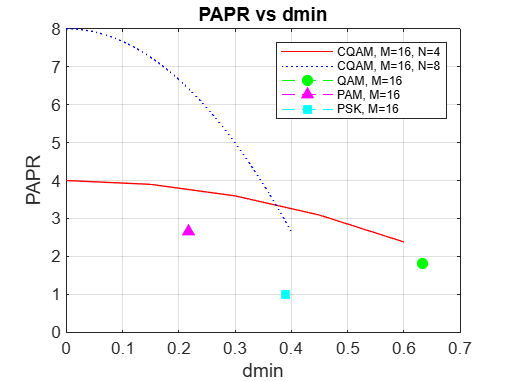


% Plot PAPR versus dmin for both cases
figure;
plot(dmins_CQAM4,paprs_CQAM4, 'r');
hold on;
plot(dmins_CQAM8, paprs_CQAM8, 'b:');
plot(dmin_QAM, PAPR_QAM, 'g--o',MarkerFaceColor='g')
plot(dmin_PAM, PAPR_PAM, 'm--^',MarkerFaceColor='m')
plot(dmin_PSK, PAPR_PSK, 'c--s',MarkerFaceColor='c')
xlabel('dmin');
ylabel('PAPR');
title('PAPR vs dmin');
legend('CQAM, M=16, N=4', 'CQAM, M=16, N=8', 'QAM, M=16', 'PAM, M=16', 'PSK, M=16', 'FontSize', 7)
grid on;

xlim([0, 0.7]);  % Set x-axis limits from 0 to 0.7
ylim([0, 8]);     % Set y-axis limits from 0 to 8

hold off;

Function definitions:

function [dmins, paprs] = evaluate_radii_metrics(R1_values, symbols_per_level, num_levels)
    dmins = zeros(1, length(R1_values));
    paprs = zeros(1, length(R1_values));
    for i = 1:length(R1_values)
        R1 = R1_values(i);
        dmin = calculate_dmin(R1, symbols_per_level);
        radii = calculate_radii(R1, dmin, num_levels, symbols_per_level);
        papr = calculate_papr(radii, num_levels);
        dmins(i) = dmin;
        paprs(i) = papr;
    end
end

function dmin = calculate_dmin(R1, symbols_per_level)
    angle_rad = 2 * pi / symbols_per_level;
    dmin = 2 * R1 * sin(angle_rad / 2);
end

function radii = calculate_radii(R1, dmin, N, symbols_per_level)
    radii = zeros(1, N);
    radii(1) = R1;
    if N > 1
        radii(2) = sqrt(dmin^2 + R1^2 - 2 * R1^2 * cos(2 * pi / symbols_per_level));
    end
    for i = 3:N
        R_prev = radii(i-1);
        R_prev_2 = radii(i-2);
        angle_diff = 2 * pi / symbols_per_level;
        R_next_from_prev = sqrt(dmin^2 + R_prev^2 - 2 * R_prev^2 * cos(angle_diff));
        angle_offset = (pi / symbols_per_level) * mod(i - (i-2), 2);
        R_next_from_prev_2 = sqrt(dmin^2 + R_prev_2^2 - 2 * R_prev_2^2 * cos(2 * angle_diff + angle_offset));
        radii(i) = max(R_next_from_prev, R_next_from_prev_2);
    end
    if N > 1
        radii(N) = sqrt(N - sum(radii(1:N-1).^2));
    end
end

function papr = calculate_papr(radii, ~)
    max_radius_squared = max(radii.^2);
    mean_radius_squared = mean(radii.^2);
    papr = max_radius_squared / mean_radius_squared;
end

function d_min = calculate_d_min(R1)
    d_min = 2 * R1;
end

function PAPR = calculate_papr_modified(R1, num_levels)
    d_min = calculate_d_min(R1);
    radii = R1;
    if R1 ~= 0
        radii(2) = sqrt(d_min^2 - R1^2);  % Correct R2 using the hypotenuse formula
    else
        radii(2) = 0;  % Avoid division by zero for R1 = 0
    end
    for i = 3:num_levels - 1
        min_radius = radii(i-2) + d_min;
        radii(i) = min_radius;
    end
    radii(num_levels) = sqrt(num_levels - sum(radii.^2));
    max_radius_squared = max(radii.^2);
    mean_radius_squared = mean(radii.^2);
    PAPR = max_radius_squared / mean_radius_squared;
end

# TASK 2:

Including one of the state-of-the-art constellation schemes for SWIPT presented in [R2]. The spikes represent points moved further from the center, increasing the PAPR (Peak-to-Average Power Ratio) of the signal.

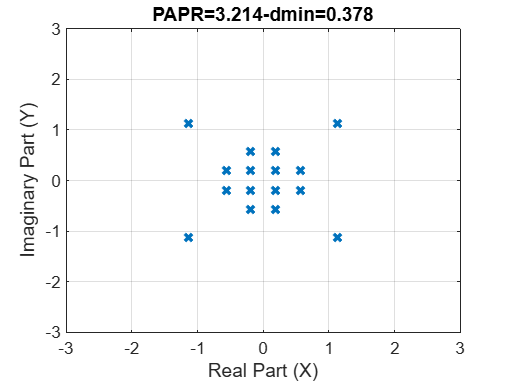

% We use the 16 spike-QAM with the specific values above
dmin_QAM = 0.378;
PAPR_QAM = 3.214;

amplitudes = (-1.5*dmin_QAM):dmin_QAM:(1.5*dmin_QAM); % Amplitude levels for both I and Q axes
[I, Q] = meshgrid(amplitudes); % Generate all possible combinations of amplitude levels for I and Q axes
s_QAM = I(:) + 1i * Q(:); % Combine the I and Q components to form complex symbols

% Sort the symbols by amplitude
[~, idx] = sort(abs(s_QAM), 'descend');

% Define the number of spikes (constellation points moved further from the center)
num_spikes = 4;

% Move the symbols with the largest amplitudes further from the center
spike_factor = 2; % Factor to determine the distance of the spikes from the center
spike_indices = idx(1:num_spikes);
spike_QAM_symbols = s_QAM;
spike_QAM_symbols(spike_indices) = spike_QAM_symbols(spike_indices) * spike_factor;

% Plot the constellation
plot(real(spike_QAM_symbols), imag(spike_QAM_symbols), 'x', LineWidth=2);
grid on;
xlabel('Real Part (X)');
ylabel('Imaginary Part (Y)');
title('PAPR=3.214-dmin=0.378');
xlim([-3, 3]);  % Set x-axis limits from -3 to 3
ylim([-3, 3]);  % Set y-axis limits from -3 to 3

hold off;

## **Verification of the results in Fig. 5 of [R1]**

Fig. 3 in [R1]  illustrates SEP versus SNR for fixed normalized  energy harvesting.  Symbol Error Probability measures the probability that a transmitted symbol is received in error. Signal-to-Noise Ratio, is a measure to quantify the ratio of the power of a desired signal to the power of background noise. In digital communications, a higher SNR generally indicates a better quality of the received signal, as the signal is stronger compared to the background noise. With a stronger signal, it becomes easier for the receiver to distinguish between different symbols, leading to a lower SER.

**16-PAM**

M = 16;% Set the number of symbols (M)
Ex1 = 1; %The energy of the symbol because of energy harvesting
Ex2 = 0.8;

% Define range of SNR values in dB
SNR_dB_PAM = 0:1:24; % Adjusted range to cover desired behavior

% Call the function to calculate SEP for each SNR value
SEP_PAM_1 = SER1(SNR_dB_PAM, Ex1, M);
SEP_PAM_2 = SER1(SNR_dB_PAM, Ex2, M);

function SEP_PAM = SER1(x, y, M)
    linear_value_x = 10.^(x / 10); % x is the Eb/No in dB

    SEP_PAM = ((2*(M-1))/ M) * qfunc(sqrt((6*4*(linear_value_x)*y)/(M^2-1))); %Calculation formula
end

**16-QAM**

SNR_dB_QAM = 0:1:24;% Adjusted range to cover desired behavior

% Call the function to calculate SEP for each SNR value
SEP_QAM_1 = SER2(SNR_dB_QAM, Ex1, M);
SEP_QAM_2 = SER2(SNR_dB_QAM, Ex2, M);

function SEP_QAM = SER2(x, y, M)
    linear_value_x = 10.^(x / 10); % x is the Eb/No in dB

    Ps_sqrtM = (2*(1-1/sqrt(M))) * qfunc(sqrt((3*4*(linear_value_x)*y)/(M-1))); %Calculation formula
    SEP_QAM = 1 - (1 - Ps_sqrtM).^2;
end

**16-CQAM**

SNR_dB_CQAM = 0:1:24;% Adjusted range to cover desired behavior

nu = ones(1, M) / M; % Probabilities

% Call the function to calculate SEP for each SNR value
SEP_CQAM_1 = SER3(SNR_dB_CQAM, Ex1, radii, nu);
SEP_CQAM_2 = SER3(SNR_dB_CQAM, Ex2, radii, nu);

function SEP_CQAM = SER3(Eb_No_dB, y, radii, nu)
    Eb_No_linear = 10 .^ (Eb_No_dB / 10.0); % Convert dB to linear scale
    Pe_sum = 0;
    for i = 1:length(radii)
        R = radii(i);
        nu_i = nu(i);
        % Skip the level if nu(i) is 0
        if nu_i == 0
            continue;
        end
        Pe_sum = Pe_sum + nu_i * qfunc(sqrt((3 * 6 * Eb_No_linear * y) / (length(radii) - 1)) * R);
    end
    SEP_CQAM = Pe_sum / sum(nu);
end


Plotting the results:

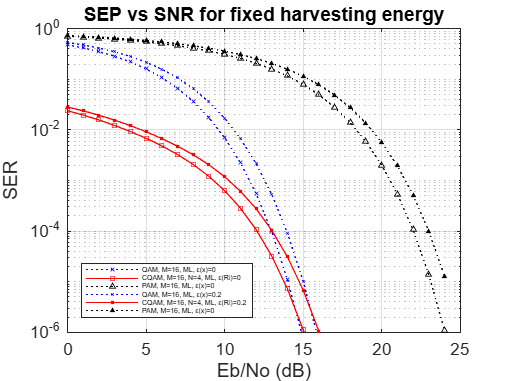

% Plot SEP versus SNR for PAM
semilogy(SNR_dB_QAM, SEP_QAM_1, 'b:x', 'MarkerSize', 3);% Semilogy is for log scale
hold on;
semilogy(SNR_dB_CQAM, SEP_CQAM_1, 'r-s', 'MarkerSize', 3);
semilogy(SNR_dB_PAM, SEP_PAM_1, 'k:^', 'MarkerSize', 3);
semilogy(SNR_dB_QAM, SEP_QAM_2, 'b:x', 'MarkerFaceColor', [0 0 1], 'MarkerSize', 2);
semilogy(SNR_dB_CQAM, SEP_CQAM_2, 'r-s', 'MarkerFaceColor', [1 0 0], 'MarkerSize', 2);
semilogy(SNR_dB_PAM, SEP_PAM_2, 'k:^', 'MarkerFaceColor', [0 0 0], 'MarkerSize', 2);
xlabel('Eb/No (dB)');
ylabel('SER');
title('SEP vs SNR for fixed harvesting energy');
ylim([1e-6 1]); % Set y-axis limit % Sets x limits from 10^-6 to 10^0
legend('QAM, M=16, ML, ε(x)=0','CQAM, M=16, N=4, ML, ε(Ri)=0', ...
    'PAM, M=16, ML, ε(x)=0', 'QAM, M=16, ML, ε(x)=0.2', ...
    'CQAM, M=16, N=4, ML, ε(Ri)=0.2', 'PAM, M=16, ML, ε(x)=0','FontSize', 4, 'Location','southwest')

grid on;